# Group comparison demonstration

This analysis script provides a demonstration of how you can compare two different groups. The approach for group comparisons is very simple. 

- Run a model to do parameter estimation for group 1. 

- Run a model to do parameter estimation for group 2.

- Then compare group-level parameters.

*THIS IS NOT A REPEATED MEASURES COMPARISON. We are just comparing group level parameter estimates*.

% define a cell array of the variables you want to compare
variables_of_interest = {'logk'};

Run setup routine

toolbox_path = fullfile(pwd,'..','ddToolbox');
addpath(toolbox_path)
ddAnalysisSetUp();

Temporarily adding toolbox subdirecties to the path: 
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/CODA
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/Data
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/DeterministicFunction
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/Variables
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/dependencies
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/dependencies/latex_fig
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/hypothesis-testing
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/models
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/models/nonparametric_models
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/models/parametric_models
	/Users/btvincent/git-local/delay-discounting-analysis/ddToolbox/models/pa

plotting defaults set





You are now up and running with:
Hierarchical Bayesian estimation and hypothesis testing for delay discounting tasks

More information available in the paper at: doi:10.3758/s13428-015-0672-2
Help can be found at: https://github.com/drbenvincent/delay-discounting-analysis/wiki




Define common properties for the parameter estimation

mcmcparams = struct('nsamples', 5000, 'nchains', 4, 'nburnin', 1000);
pointEstimateType = 'median';
sampler = 'jags';
shouldPlot = 'no';

Define paths to the datasets

datapath1 = fullfile(pwd,'datasets','group_comparison','group1');
datapath2 = fullfile(pwd,'datasets','group_comparison','group2');

group1files = allFilesInFolder(datapath1, 'txt');
group2files = allFilesInFolder(datapath2, 'txt');

# Conduct parameter estimation on the datasets

group1 = ModelHierarchicalLogK(...
	Data(datapath1, 'files', group1files),...
	'savePath', fullfile(pwd,'output','group1'),...
	'pointEstimateType', pointEstimateType,...
	'sampler', sampler,...
	'shouldPlot', shouldPlot,...
	'shouldExportPlots', false,...
	'mcmcParams', mcmcparams);

You have created a Data object


ans =    1


A copy of the group-level dataset just constructed has been saved as a text file:
/Users/btvincent/git-local/delay-discounting-analysis/demo/datasets/group_comparison/group1/groupLevelData/COMBINED_DATA.txt


The following data files were imported:


    'AB-C-2016Feb12-10.47.txt'
    'AD-C-2016Feb26-14.32.txt'
    'AH-C-2016Feb23-14.09.txt'
    'AT-C-2016Feb26-12.26.txt'
    'BD-C-2016Feb09-17.28.txt'
    'DG-C-2016Feb25-17.04.txt'
    'JDA-C-2016Feb09-16.34.txt'
    'JSL-C-2016Feb25-12.25.txt'
    'RR-C-2016Feb23-13.35.txt'
    'SE-C-2016Feb24-15.21.txt'




Running JAGS (4 chains, 1250 samples each)
Running chain 3 (parallel execution)
Running chain 4 (parallel execution)
Running chain 1 (parallel execution)
Running chain 2 (parallel execution)
Calculating statistics


Calculating posterior predictive measures...


ans =    1



Rhat for: logk	AB-C-2016Feb12-10.47:	1.00011	
AD-C-2016Feb26-14.32:	0.99971	
AH-C-2016Feb23-14.09:	0.99983	
AT-C-2016Feb26-12.26:	1.00077	
BD-C-2016Feb09-17.28:	1.00016	
DG-C-2016Feb25-17.04:	1.00154	
JDA-C-2016Feb09-16.34:	1.00059	
JSL-C-2016Feb25-12.25:	0.99987	
RR-C-2016Feb23-13.35:	1.00134	
SE-C-2016Feb24-15.21:	1.00012	
GROUP:	0.99969	

Rhat for: alpha	AB-C-2016Feb12-10.47:	1.00761	
AD-C-2016Feb26-14.32:	1.00695	
AH-C-2016Feb23-14.09:	1.00350	
AT-C-2016Feb26-12.26:	1.02883	(WARNING: poor convergence)
BD-C-2016Feb09-17.28:	1.00478	
DG-C-2016Feb25-17.04:	1.00105	
JDA-C-2016Feb09-16.34:	1.05566	(WARNING: poor convergence)
JSL-C-2016Feb25-12.25:	1.00989	
RR-C-2016Feb23-13.35:	1.01464	(WARNING: poor convergence)
SE-C-2016Feb24-15.21:	1.00716	
GROUP:	1.00237	

Rhat for: epsilon	AB-C-2016Feb12-10.47:	1.00230	
AD-C-2016Feb26-14.32:	1.00292	
AH-C-2016Feb23-14.09:	1.00158	
AT-C-2016Feb26-12.26:	1.00588	
BD-C-2016Feb09-17.28:	1.00349	
DG-C-2016Feb25-17.04:	1.00189	
JDA-C-2016Feb09-16.34:	1.

finalTable =                              logk_mean    alpha_mean    epsilon_mean     Var1      Var2      Var3
                             _________    __________    ____________    ______    _______    ____

    AB-C-2016Feb12-10.47     -8.7306      2.3828        0.050732        14.789    0.86111      0 
    AD-C-2016Feb26-14.32     -5.5124       2.227        0.056513        10.748    0.77778      0 
    AH-C-2016Feb23-14.09     -3.6425      2.4263        0.073635        8.0901       0.75      0 
    AT-C-2016Feb26-12.26     -5.4064      2.9721        0.094143        8.8168       0.75      0 
    BD-C-2016Feb09-17.28     -4.5519      2.3017        0.056437        11.429    0.80488      0 
    

ans =    1


Table was exported to:
	/Users/btvincent/git-local/delay-discounting-analysis/demo/output/group1/parameterEstimates_Posterior_median.csv


Methods for class ModelHierarchicalLogK:

ModelHierarchicalLogK                   exportParameterEstimates                plot                                    
conditionalDiscountRates                getGroupLevelSamples                    plotMCMCchains                          
conditionalDiscountRates_GroupLevel     get_inferred_present_subjective_values  postSamplingActivities                  
conductInference                        get_nChains                             
experimentPlot                          initialiseChainValues                   



group2 = ModelHierarchicalLogK(...
	Data(datapath2, 'files', group2files),...
	'savePath', fullfile(pwd,'output','group2'),...
	'pointEstimateType', pointEstimateType,...
	'sampler', sampler,...
	'shouldPlot', shouldPlot,...
	'shouldExportPlots', false,...
	'mcmcParams', mcmcparams);

You have created a Data object


ans =    1


A copy of the group-level dataset just constructed has been saved as a text file:
/Users/btvincent/git-local/delay-discounting-analysis/demo/datasets/group_comparison/group2/groupLevelData/COMBINED_DATA.txt


The following data files were imported:


    'AB-F-2016Feb29-09.45.txt'
    'AD-F-2016Feb12-11.19.txt'
    'AH-F-2016Feb10-10.19.txt'
    'AT-F-2016Feb12-09.21.txt'
    'BD-F-2016Feb23-11.09.txt'
    'DG-F-2016Feb11-11.46.txt'
    'JDA-F-2016Feb24-09.20.txt'
    'JSL-F-2016Feb11-10.47.txt'
    'RR-F-2016Feb12-10.10.txt'
    'SE-F-2016Feb10-09.24.txt'




Running JAGS (4 chains, 1250 samples each)
Running chain 3 (parallel execution)
Running chain 2 (parallel execution)
Running chain 1 (parallel execution)
Running chain 4 (parallel execution)
Calculating statistics


Calculating posterior predictive measures...


ans =    1



Rhat for: logk	AB-F-2016Feb29-09.45:	0.99965	
AD-F-2016Feb12-11.19:	0.99976	
AH-F-2016Feb10-10.19:	1.00039	
AT-F-2016Feb12-09.21:	1.00136	
BD-F-2016Feb23-11.09:	1.00160	
DG-F-2016Feb11-11.46:	1.00047	
JDA-F-2016Feb24-09.20:	1.00034	
JSL-F-2016Feb11-10.47:	1.00054	
RR-F-2016Feb12-10.10:	1.00036	
SE-F-2016Feb10-09.24:	1.00013	
GROUP:	0.99990	

Rhat for: alpha	AB-F-2016Feb29-09.45:	1.00406	
AD-F-2016Feb12-11.19:	1.00086	
AH-F-2016Feb10-10.19:	1.00790	
AT-F-2016Feb12-09.21:	1.00437	
BD-F-2016Feb23-11.09:	1.00732	
DG-F-2016Feb11-11.46:	1.00292	
JDA-F-2016Feb24-09.20:	1.00035	
JSL-F-2016Feb11-10.47:	1.00170	
RR-F-2016Feb12-10.10:	1.00224	
SE-F-2016Feb10-09.24:	1.00283	
GROUP:	1.00095	

Rhat for: epsilon	AB-F-2016Feb29-09.45:	1.00030	
AD-F-2016Feb12-11.19:	1.00034	
AH-F-2016Feb10-10.19:	1.00000	
AT-F-2016Feb12-09.21:	1.00145	
BD-F-2016Feb23-11.09:	1.00059	
DG-F-2016Feb11-11.46:	1.00338	
JDA-F-2016Feb24-09.20:	1.00133	
JSL-F-2016Feb11-10.47:	1.00079	
RR-F-2016Feb12-10.10:	1.00129	
SE-F-2016Fe

finalTable =                              logk_mean    alpha_mean    epsilon_mean     Var1      Var2      Var3
                             _________    __________    ____________    ______    _______    ____

    AB-F-2016Feb29-09.45     -8.6053      2.5807        0.069091        14.342    0.88889      0 
    AD-F-2016Feb12-11.19      -2.919      3.0851        0.086624         9.348    0.80556      0 
    AH-F-2016Feb10-10.19     -5.8855      2.1001        0.042365        14.318    0.86111      0 
    AT-F-2016Feb12-09.21     -1.8378       3.103        0.088792        6.2656    0.72222      0 
    BD-F-2016Feb23-11.09     -2.7335      2.1007        0.058611        10.293    0.80556      0 
    

ans =    1


Table was exported to:
	/Users/btvincent/git-local/delay-discounting-analysis/demo/output/group2/parameterEstimates_Posterior_median.csv


Methods for class ModelHierarchicalLogK:

ModelHierarchicalLogK                   exportParameterEstimates                plot                                    
conditionalDiscountRates                getGroupLevelSamples                    plotMCMCchains                          
conditionalDiscountRates_GroupLevel     get_inferred_present_subjective_values  postSamplingActivities                  
conductInference                        get_nChains                             
experimentPlot                          initialiseChainValues                   



# Do the comparison

**NOTE: this works but is under development, so the exact way we invoke model comparison is likely to change in the future**

You will typically want to pick one method and stick with that. Below is a demonstration of each approach.

## METHOD 1: Parameter Estimation approach

Now you can make decisions about whether there are group level differences based upon whether the 95% credible region overlaps with zero (ie no group difference) or not.

ans =   UnivariateDistribution with properties:

      mean: -0.4355
    median: -0.3822
      mode: 0.1493


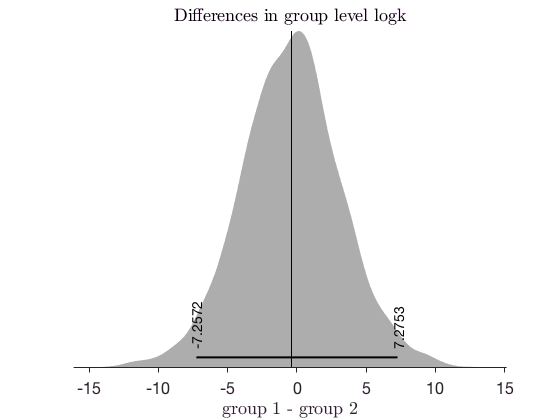

group1_minus_group2 = group_comparison(...
	group1,...
	group2,...
	variables_of_interest,...
	pointEstimateType,...
	'parameter estimation');

## METHOD 2: Hypothesis testing approach

TODO: Description here

group1_minus_group2 = group_comparison(...
	group1,...
	group2,...
	variables_of_interest,...
	pointEstimateType,...
	'bayesian hypothesis test');

## METHOD 3: Estimation with point estimates

TODO: Description here

group1_minus_group2 = group_comparison(...
	group1,...
	group2,...
	variables_of_interest,...
	pointEstimateType,...
	'point estimates');